**Survey**: About how long did it take you to complete each of the three sections of this homework?

concept_duration = 3;  %REPLACE WITH YOUR ANSWER IN HOURS%
theory_duration = 2;  %REPLACE WITH YOUR ANSWER IN HOURS%
implementation_duration = 6;  %REPLACE WITH YOUR ANSWER IN HOURS%

**Instructions**: It is very important you follow these instructions exactly. It will make grading easier, quicker, and more accurate:

- For your answers, please use the variables specified after '*Expected output variables:*' for each question. 

**Question 1**: Impulse responses

*Expected output variables: ***h1**, **h2**

% SETUP
n = 0:10;

% ANSWER
h1 = n-2 == 0; 
h2 = (n==0) - (n-4 ==0); 

% PLOT
disp('Question 1 Figures')

Question 1 Figures


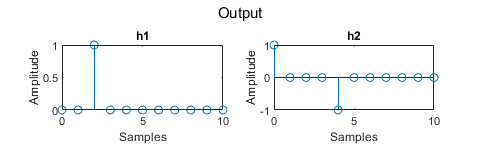

figure; sgtitle('Output');
subplot(1, 2, 1); stem(n, h1); title('h1');
xlabel('Samples'); ylabel('Amplitude');
subplot(1, 2, 2); stem(n, h2); title('h2');
xlabel('Samples'); ylabel('Amplitude');
set(gcf, 'Units', 'Inches', 'Position',[0 0 5 1.5])

**Question 2**: Convolution and Correlation

*Expected output variables:* **x1*** (for input signal); ***h1**, **h2**, **h3**, **h4**, **h**5* (for the impulse responses); ***y1**, **y2**, **y3**, **y4**, **y5*** (for the processed signals), ****ans1**** (for answer to part f)*

% SETUP
n = 0:10;

% ANSWER
x1 = (n>=0) - 2*(n-2>=0) + (n-4>=0); 
h1 = n-2 == 0; 
h2 = (n==0) - (n-4==0); 
h3 = flip(x1); 
h4 = flip(conv(x1, (n-4==0))); 
h5 = flip(conv(x1, (n-4==0))) + 2; 

y1 = conv(x1, h1); 
y2 = conv(x1, h2); 
y3 = conv(x1, h3); 
y4 = conv(x1, h4); 
y5 = conv(x1, h5); 

ans1 = ['The convolution result is the correlation of these 2 signals. The maximum value appears' ...
    ' at the most similar part of 2 signals. The possible maximum value will be sum(|x[n]|^2) ,' ...
    'which means one signal is some part of the other and they perfectly matched.'];


% PLOT
disp('Question 2 Figures')

Question 2 Figures


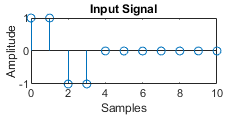

figure; 
set(gcf, 'Units', 'Inches', 'Position',[0 0 2.5 1.2])
stem(n, x1); title('Input Signal');
xlabel('Samples'); ylabel('Amplitude');

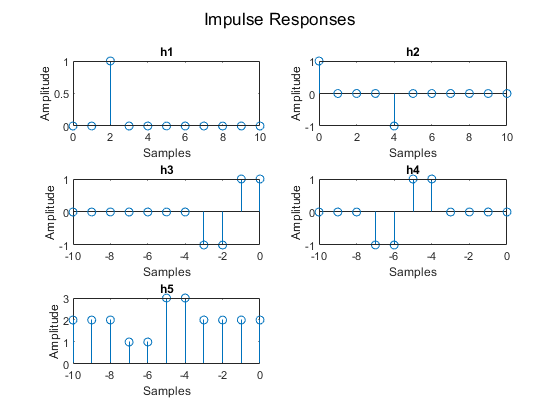


figure;  sgtitle('Impulse Responses');
subplot(3,2,1); stem(n, h1); title('h1');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,2); stem(n, h2); title('h2');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,3); stem(-10:0,h3); title('h3');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,4); stem(-10:0, h4(11:21)); title('h4');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,5); stem(-10:0, h5(11:21)); title('h5');
xlabel('Samples'); ylabel('Amplitude');

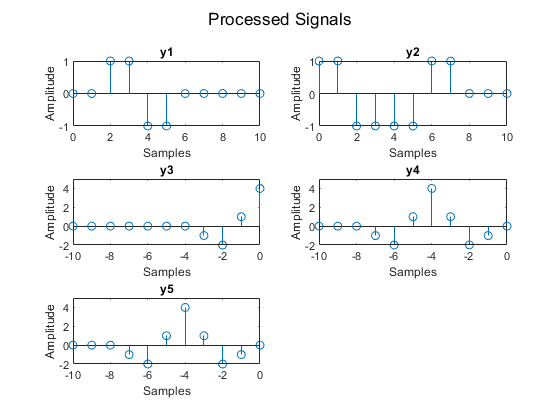


figure;  sgtitle('Processed Signals');
subplot(3,2,1); stem(n, y1(1:11)); title('y1');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,2); stem(n, y2(1:11)); title('y2');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,3); stem(-10:0, y3(1:11)); title('y3');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,4); stem(-10:0, y4(11:21)); title('y4');
xlabel('Samples'); ylabel('Amplitude');
subplot(3,2,5); stem(-10:0, y5(11:21)); title('y5');
xlabel('Samples'); ylabel('Amplitude');

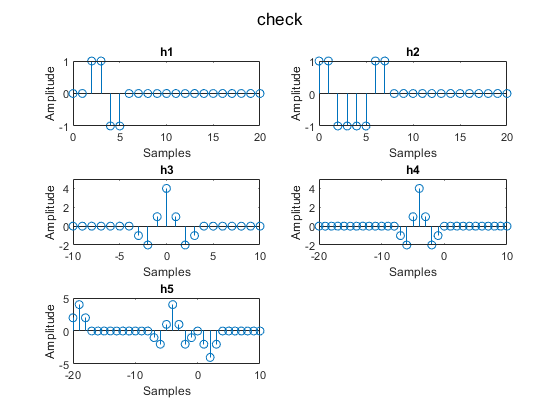


% Final Result Trim
h4 = h4(11:21);
h5 = h5(11:21);

% y1 = y1(1:11);
% y2 = y2(1:11);
% y3 = y3(1:11);
% y4 = y4(11:21);
% y5 = y5(11:21);

% New variable n_outN for yN, instead of trims
n_out1 = 0:20; 
n_out2 = 0:20; 
n_out3 = -10:10; 
n_out4 = -20:10; 
n_out5 = -20:10; 


**Question 3**: Finding a hidden signal

*Expected output variables: ***code_first_index**

% LOAD DATA
load('2020_eee5502_code2.mat')

% GET DATA INFO
lc = length(code);
lm = length(message);

% CORRELATION
code_flipped = flip(code);
result = conv(code_flipped, message);

[val, idx] = max(result);
code_first_index = idx-lc+1; 



% PLOT
x = 1:lm;
filled_code = zeros(size(message));
filled_code(1:code_first_index) = nan;
filled_code(code_first_index:code_first_index+lc-1) = code;
filled_code(code_first_index+lc+1:end) = nan;


disp('Question 3 Figures')

Question 3 Figures


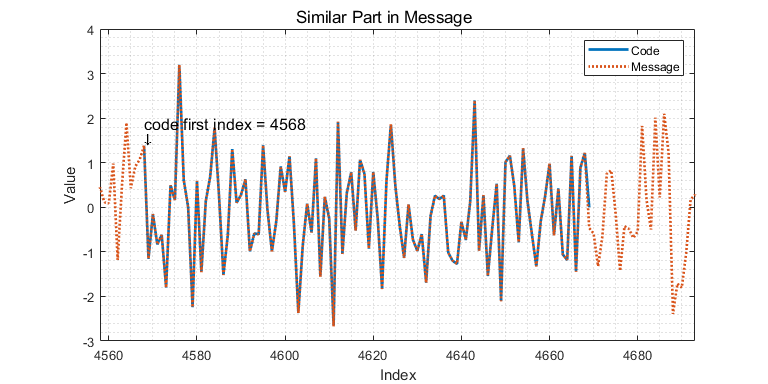

figure; sgtitle('Similar Part in Message')
plot(x, filled_code, x, message, ':', "LineWidth",2)
xlim([code_first_index-10, code_first_index+125])
xlabel('Index'); ylabel('Value'); 
legend('Code', 'Message')
grid minor
set(gcf, 'Units', 'Inches', 'Position',[0 0 8 4])
text(code_first_index,code(1)+0.2,'\downarrow', 'FontWeight','bold')
text(code_first_index,code(1)+0.5,'code first index = 4568', 'FontSize',12)

**Final Instructions**: It is very important you follow these instructions exactly. It will make grading easier, quicker, and more accurate:

- Do not change the name of this file nor the accompanying files and functions.

- When complete, select all six files (this MATLAB Live Script and the five MATLAB Script functions) and zip them into a folder named "codeN_UFID" where UFID is your eight digit UFID number and N is the HW number. Ensure the files are zipped directly. Do not put them in a folder then zip that folder.  

- Submit the resulting zipped folder to canvas for this assignement. It is alright if canvas adds something to the end of the file name, such as '-1'.